# Time-frequency representations of power

## **Introduction**

Time-frequency representations of power are used to quantify brain  responses in the frequency domain. These reposes are often interpreted  to reflect task-related modulations of brain oscillations. In this  section we will show how these response can be estimated by an FFT  approach using a sliding time-window.  

## **Preparation**

Make sure FieldTrip is installed and path is set. Then run ft_defaults (only needs running once during each Matlab session). 

ft_defaults

Set the path and the file names of the fif files. We will be using the MaxFiltered data.

data_path = 'C:\Users\Tamas\Documents\';%'C:\Users\JensenO\Dropbox\FLUX\Development\dataRaw\';

Load the cleaned planar gradiometer data. 

data=[data_path,'planar_clean.mat']; 
load(data)

Select 'attend left' trials and 'attend right' trials for the two conditions. 

idx=(find(planar_clean.trialinfo(:,1)==21))';
cfg=[];
cfg.trials=idx;
data_left=ft_selectdata(cfg,planar_clean);
clear idx

idx=(find(planar_clean.trialinfo(:,1)==22))';
cfg=[];
cfg.trials=idx;
data_right=ft_selectdata(cfg,planar_clean);

## **Time-frequency analysis of slower frequencies (<30 hz)**

From experience we know that oscillations in slower frequency bands such as in the theta, alpha and beta range are fairly narrow-band (ΔF ~ 2  Hz) whereas neuronal activity in the gamma band (60 - 90 hz) is  typically more broad-band (ΔF ~ 5-10 hz). For this reason we advise the  use different settings for slower and faster frequencies.

The goal is to calculate the time-frequency of power per trials. The  power will subsequently be averaged over trials. To calculate the power a Fourier transform is applied to a sliding time-window approach. The  length of the time-window (cfg.t_fimwin) is ΔT = 0.5 s. It will be moved in time steps of 0.05 s starting at -1.8 and ending at 1 (cfg.toi).  Prior to calculating the Fourier transform the time window is multiplied by a Hanning taper (also length ΔT). The analysis will be performed  from 1 to 30 Hz in steps of Δf = 2 Hz (cfg.foi). Note that the frequency  steps are dictated by the length of the sliding time-window:  Δf = 1/ΔT. The spectra smoothing is about ΔFs = 1.5 / ΔT = ±3 Hz (the factor 1.5 stems for the Hanning taper).  

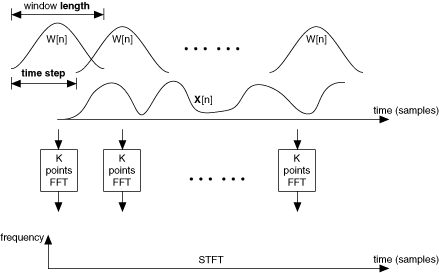

Calculate the time-frequency power for both conditions:  

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'hanning';
cfg.method = 'mtmconvol';
cfg.foi          = 2:2:30;
numfoi = length(cfg.foi);
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.5;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_low_left = ft_freqanalysis(cfg, data_left);
tfr_low_right = ft_freqanalysis(cfg, data_right);

The TFRs of power for the 204 planar gradiometers have now been produced. Recall that the Elekta/MEGIN system has 306 sensor locations. Each location has two orthogonal planar gradiometers. 

The next step is to combine the power of two  gradiometers by a summing those:  

cfg = [];
cfg.method = 'sum';
tfr_low_left_c = ft_combineplanar(cfg,tfr_low_left);
tfr_low_right_c = ft_combineplanar(cfg,tfr_low_right);

This results in 102 TFRs of each of the conditions. 

### **Plotting the TFR of the low frequency results**

In the following analysis we will focus on the time following the  target onset and 'attend left' trials only. Lets first consider the TFR  plot of a single channel (MEG2112): 

cfg = [];
cfg.baseline     = 'no'; 
cfg.xlim         = [-0.5 1];
cfg.zlim         = [0 0.7e-23] ;	        
cfg.showlabels   = 'no';	

cfg.zlim         = [-5.5e-24 5.5e-24] ;
cfg.channel = 'MEG2112';
ft_singleplotTFR(cfg, tfr_low_left);


The power spans from 0 to 0.7e-23. The units are in (T/m)2/Hz. To convert to (fT/m)2/Hz multiply by 1026, i.e. the range is in 0 to 1500 (ft/m)2. In the plot note the ongoing alpha activity at ~10 Hz prior to the onset of the gratings. In response to  the cue and stimulus onset there is ~4 to 6 Hz response most likely  reflecting the spectral content of the event-related field.  

To observe the change in power we apply relative baseline (-0.5 to -0.25 s; i.e. just prior to the target onset) (powerpost/powerpre). Note ~100% decrease of power in the alpha band after the grating onset  (time 0s) until the end of the analysed window. In addition note the  short-lived over 100% response in the theta band at the grating onset.  This respons in the theta band likely reflecting the spectral  representation of the event-related field rather than induced  oscillations.  

cfg = [];
cfg.baseline     = [-0.5 -0.25]; 
cfg.baselinetype = 'relative';
cfg.xlim         = [-0.5 1];      
cfg.showlabels   = 'no';	
cfg.zlim         = [0.4 1.7] ;	
cfg.channel = 'MEG2112';
ft_singleplotTFR(cfg, tfr_low_left);

### Question 1

- Plot the results using an absolute baseline. Why is a relative baseline typically used in group studies?

To show the the modulation in power for all sensor arranged topographically write: 

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.4 2] ;	        
cfg.layout = 'neuromag306planar.lay';
ft_multiplotTFR(cfg, tfr_low_left);
title('TFR of power <30 Hz')

Plot the modulation of power of the combined gradiometers, which gives a plot that is easier to interpret.

cfg.layout = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_low_left_c);


### **Question 2**

Plot the results using an absolute baseline. Why is a relative baseline typically used in group studies?  

### **Question 3**

Change the time-window to 0.25 s and plot the results. What is the  main effect in terms of time and frequency smoothing? 

### **Question 4**

Change the time-window to 1.00 s and plot the results. What is the  main effect  in terms of time and frequency smoothing?  

To show a topographic map of the alpha depression (10 hz) in the time interval from 350 to 1000 ms use the ft_topoplotTFR function

cfg = [];
cfg.baseline     = [-0.5 -0.3]; 
cfg.baselinetype = 'relative';
cfg.xlim=[0.35 1];
cfg.ylim = [10 10];
cfg.zlim         = [0.5 1.5] ;	        
cfg.showlabels   = 'no';	
cfg.layout = 'neuromag306cmb.lay';
figure 
ft_topoplotTFR(cfg, tfr_low_left_c);

### **Question 5**

Repeat the analysis with the 'attend right' trials. Are there any differences from the results of the 'attend left' trials? 

## Comparing attend right versus attend left

The alpha activty in the cue-stimulus interval is known to be highly  modulated by spatial attention. Specifically, numerous studies have  demonstrated that posterior alpha power decrease in the hemisphere  contralateral to attended direction whereas it increases relatively  inthe ipsilateral hemisphere. To identify this effect we will illustrate the alpha modulation in the cue-stimulus interval (-0.5 to 0 s). This  will be done by calculating the power lateralization index:

           
$$\mathrm{power}\;\mathrm{lateralization}\;\mathrm{index}=\frac{{\mathrm{power}}_{\mathrm{att},\mathrm{right}} -{\mathrm{power}}_{\mathrm{att},\mathrm{left}} }{{\mathrm{power}}_{\mathrm{att},\mathrm{right}} +{\mathrm{power}}_{\mathrm{att},\mathrm{left}} }$$


Note that this measures is calculated without performing baseline correction.

tfr_low_diff=tfr_low_right_c;
tfr_low_diff.powspctrm=(tfr_low_right_c.powspctrm-tfr_low_left_c.powspctrm)./(tfr_low_left_c.powspctrm+tfr_low_right_c.powspctrm);

To show the *power lateralization index* for all combined sensors write:

cfg = [];
cfg.xlim=[-0.5 0];
cfg.zlim         = [-0.3 0.3] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_low_diff);
title('Right-Left')

Then plot the topography of the alpha repsonse at 10Hz and focus on the  timewindow between the cue onset (-0.5 sec) and grating onset (0 sec).  Lateralized attention shift has repeatedly been reported in the  literature indexed by alpha power lateralization well after the cue just prior to the target onset.   

cfg = [];
cfg.xlim = [-0.5 0];
cfg.ylim = [10 10];
cfg.zlim         = [-0.15 0.15] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_low_diff);

The resulting plot indicate strong lateralization of the alpha  response over a number of posterior channels when comparing the 'attend  left' and 'attend right' trials. 

To study the topography as a function of time write:  

cfg = [];
cfg.xlim = [-0.6:0.2:0.6];
cfg.ylim = [10 10];
cfg.zlim         = [-0.3 0.3] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_low_diff);

## **Time-frequency analysis of faster frequencies (>30 hz)**

For higher frequencies, a multitaper approach is typically applied.  The multitapers serve to smooth the time-frequency representations in  the frequency domain. The smoothing will increase with number of tapers. Since oscillatory gamma activity (~60-90 Hz) often is quite broadband  more spectral smoothing is required compared to lower frequencies.  Several orthogonal tapers might be used for each time window prior to the calculation of the Fourier transform.  The length of the time-window (cfg.t_fimwin) is ΔT = 0.25 s. It will be moved in steps of 0.05 s  starting at -1.5 and ending at 1.5 (cfg.toi). The analysis will be  performed from 30 to 100 Hz in steps of Δf = 4 Hz (cfg.foi) since the  frequency steps are dependent on the length of the time-window ( Δf =  1/ΔT).  

The number of tapers is dependent on ΔT and the required smoothing ΔFs. We chose ΔFs = 10 (cfg.tapsmofrq). The resulting tapers are defined as  

`K = 2*ΔT*ΔF``s``-1 `

where K is an integer required to be larger than 0.  

i.e. K = 2*0.25 * 10 - 1  = 4 tapers. Note the smoothing is ±10  i.e. about 20 Hz total (see Percival and Walden, 1993). Also keep in  mind that it does not make sense to reduce the smoothing to only having  one taper. In that case use a Hanning taper instead.  

Run the time-frequency analysis of power on the 'attend left' and 'attend right' trials separately.  

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'dpss';
cfg.tapsmofrq  = 10; 
cfg.method = 'mtmconvol';
cfg.foi          = 30:2:100;
numfoi = length(cfg.foi);
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.25;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_high_left = ft_freqanalysis(cfg, data_left);
tfr_high_right = ft_freqanalysis(cfg, data_right);

Combine the power of two orthogonal gradiometers at the same location:  

cfg = [];
cfg.method = 'sum';
tfr_high_left_c = ft_combineplanar(cfg,tfr_high_left);
tfr_high_right_c = ft_combineplanar(cfg,tfr_high_right);

### **Plotting the TFR of the high frequency results**

The outcome of the TFR analysis of the 'attend left' trials will now be plotted on a single senor (MEG1923) with respect to a relative baseline (post-power / pre-power). The baseline interval is -0.5 to -0.3 s.  

cfg = [];
cfg.baseline     = [-0.5 -0.25]; 
cfg.baselinetype = 'relative';
cfg.xlim         = [-0.5 1];      
cfg.showlabels   = 'no';	
cfg.zlim         = [0.7 1.3] ;	
cfg.channel = 'MEG1923';
ft_singleplotTFR(cfg, tfr_high_left);

Note the increase in 80-90 Hz gamma power in response to the onset (t = 0 s) of the gratings.

Plot the combined gradiometers  (MEG1922+1923).

cfg = [];
cfg.baseline     = [-0.5 -0.25]; 
cfg.baselinetype = 'relative';
cfg.xlim         = [-0.5 1];      
cfg.showlabels   = 'no';	
cfg.zlim         = [0.6 1.4] ;	
cfg.channel = 'MEG1922+1923';
ft_singleplotTFR(cfg, tfr_high_left_c);

To show the TFRs for all combined sensors write:

cfg = [];
cfg.baseline     = [-0.5 -0.125]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.6 1.4] ;	        
cfg.showlabels   = 'no';	 
cfg.layout       = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_high_left_c);
title('TFR of power >30 Hz')

The time-frequency response of the induced power. A relative baseline (-0.5 to -0.125 s) has been applied. Note the induced gamma band response over a couple of posterior sensors.  

For the topographic representation for gamma activity in response to the gratings write:

cfg = [];
cfg.baseline     = [-0.5 -0.125]; 
cfg.baselinetype = 'relative';
cfg.xlim = [0 0.6];
cfg.ylim = [60 90];
cfg.zlim         = [0.8 1.2] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_high_left_c);

Here appreciate the posterior distribution of the gamma band activity.

Next, calculate the *power lateralization index* (using the same equations as for the lower frequencies).

tfr_high_diff=tfr_high_right_c;
tfr_high_diff.powspctrm=(tfr_high_right_c.powspctrm-tfr_high_left_c.powspctrm)./(tfr_high_right_c.powspctrm+tfr_high_left_c.powspctrm);

and display for all sensors:

cfg = [];
cfg.xlim=[0 1];
cfg.zlim         = [-0.2 0.2] ;	  
cfg.showlabels   = 'no';	 
cfg.layout       = 'neuromag306cmb.lay';
ft_multiplotTFR(cfg, tfr_high_diff);
title('Right - Left')

as well as the topographic plots:

cfg = [];
cfg.xlim = [0 0.6];
cfg.ylim = [60 90];
cfg.zlim         = [-0.05 0.05] ;	        
cfg.showlabels   = 'no';	
cfg.layout       = 'neuromag306cmb.lay';
ft_topoplotTFR(cfg, tfr_high_diff);

### Question 6

Compare the gamma lateralization to the  alppha lateralization. Interpret the alpha and gamma band lateralization in relation to neuronal processing and functional inhibition.

### Question 7

Change the smoothing to 20 Hz. How many  tapers does this result in? What are the consequences for the  time-frequency representation?

### **Question 8**

Perform the time-frequency analysis with a Hannning taper for the gamma band first with the 'attend left' trials: 

cfg = [];
cfg.output = 'pow';
cfg.channel = 'MEGGRAD';
cfg.taper = 'hanning';
cfg.method = 'mtmconvol';
cfg.foi          = 30:4:100;
cfg.t_ftimwin    =  ones(length(cfg.foi),1).* 0.25;
cfg.toi          = [-1.8 : 0.05: 1];
cfg.keeptrials = 'no'; 
tfr_han_left = ft_freqanalysis(cfg, data_left);

cfg = [];
cfg.method = 'sum';
tfr_han_left_c = ft_combineplanar(cfg,tfr_han_left);

cfg = [];
cfg.baseline     = [-0.5 -0.125]; 
cfg.baselinetype = 'relative';
cfg.xlim=[-0.5 1];
cfg.zlim         = [0.6  1.4] ;	        
cfg.showlabels   = 'no';	
cfg.channel = 'MEG1922+1923'; 
ft_singleplotTFR(cfg, tfr_han_left_c);

### **Question 9**

Do the same for the 'attend right' trials. 

In which way does the multitapers improves the estimate and why? 

### **Question 10**

Calculate and plot the difference between the 'attend left' and  'attend right' at 30Hz to 100Hz. Show the plots. Is there any difference between the two conditions in the gamma band? 

## **Publications and preregistration**

It is essential to report all the parameters in the frequency  analysis both when submitting a preregistration and a manuscript. Note  that the analysis based on a standard spectral analysis and should be  independent on the toolbox applied.  

Example for publications text: "The time-frequency representations were calculated using a sliding  time-window approach applied to the single trials. For frequencies lower than 30 Hz we used a 500 ms time-window moved in steps of 50 ms. A  Hanning window was multiplied to each time-window prior to calculating  the discrete Fourier transform. This resulted in ±3 Hz spectral  smoothing. The power was than estimated as the modulus square of the  Fourier transform. This was done for 1 to 30 Hz in steps of 2 Hz.  

For frequencies above 30 Hz a multi-taper method approach was  used involving a sliding time-window of 0.25 s. To ensure sufficient  spectral smoothing to the detect the gamma activity, a set of tapers  derived from discrete prolate spheroidal (DPSS), or Slepian sequences,  were multiplied to the time-windowed data. We used 4 tapers resulting in a spectral smoothing of ~±10 Hz. Following a discrete Fourier transform the power estimate for the respective tapers were averaged. This was  done for 30 to 100 Hz in steps of 4 Hz.  

The power-estimated per trial were averaged. The relative change  in power was then considered with respect to a baseline of -0.3 to 0.5  ms. " 

## **Background material**

-  Tallon-Baudry and Bertrand (1999) Oscillatory gamma activity in humans and its role in object representation. Trends Cogn Sci.  3(4):151-162

-  Mitra and Pesaran (1999) Analysis of dynamic brain imaging data. Biophys J. 76(2):691-708

-  Percival and Walden, 1993 Spectral analysis for physical  applications: multitaper and conventional univariate techniques.  Cambridge, UK: Cambridge UP.